## **Clearing everything**

clc; 
clear all; 
close all; 

## Data of the algorithm

% Asking the values of number of clusters and itertions
k= input("Number of clusters required:"); % Number of clusters
iterations= input("Number of iterations required:"); % Number of iterations (epoch)

## Generating random data points

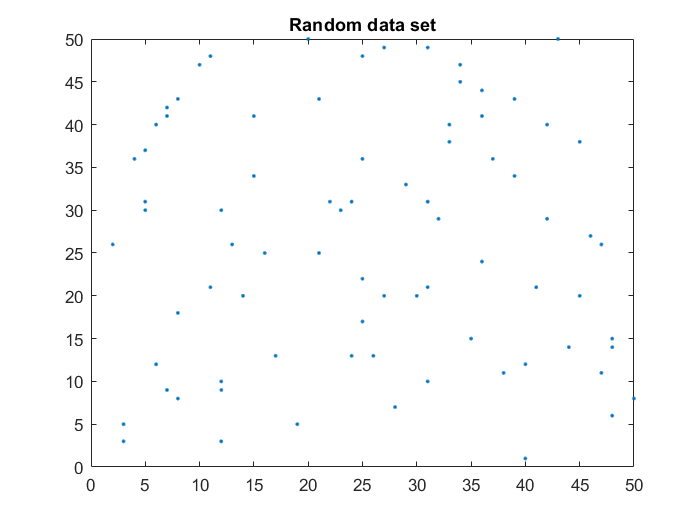

% Asking for the number of points to be generated
n=input("Number of random data points required:"); % n is the number of points generated
x=randi([1,50],n,1); % some random data as x vector
y=randi([1,50],n,1); % some random data as y vector
plot(x,y,'.') % plotting the sampled data
title("Random data set"); % Giving title to the above plot

## Initial values of the centroids

% initialising some random cluster centroids

x_centroid = randi([1,50],k,1); % randomly initiating the centre for x vector
y_centroid = randi([1,50],k,1); % randomly initiating the centre for y vector

## Iterations

for p=1:iterations
    for i=1:n
        for j=1:k
            if p==1
                Dist_euc(i,j)=sqrt(((x(i))-(x_centroid(j)))^2+((y(i))-(y_centroid(j)))^2);% Calculating the euclidean 
                % distance for the set of points with the initialized set of centroids and this is the sample for jth centroid
            else
                Dist_euc(i,j)=sqrt(((x(i))-(x_new_centroid(j)))^2+((y(i))-(y_new_centroid(j)))^2); % Calculating the euclidean 
                % distance for the set of points with the initialized set of centroids
            end
        end
        % Defining clusters
        [minidist, CN] = min(Dist_euc(i,1:k)); % minimum distance and the cluster which the sample belongs to
        
        Distance(p,i)=minidist;
        Clus_num(p,i)=CN;
    end
    % Recomputing the centroids for the clusters
    for q=1:k
        Clus_pos=(Clus_num(p,:)==q); % Position of the points of the cluster
        Clus_points(q,:)=Clus_pos; % Points of the cluster
        x_new_centroid(q,:)=mean(x(Clus_pos)); % New cluster centroid in x
        y_new_centroid(q,:)=mean(y(Clus_pos)); % New cluster centroid in y
    end
    Clus_centre_iteration_x(p,:)=x_new_centroid; % Cluster centre at each iteration in x
    Clus_centre_iteration_y(p,:)=y_new_centroid; % Cluster centre at each iteration in y
    Clus_points_iteration(p,:,:)=Clus_points; % points of cluster at each iteration
end

## Plot of the movements of the centroids and clusters

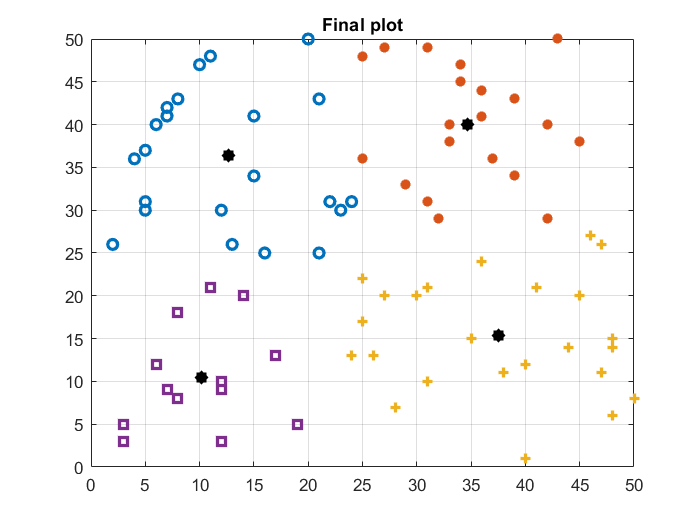

CV= 'o*+s^v.db+c+m+k+yorobocomokoysrsbscsmsksy'; % Color Vector
for p=1:iterations+1
    figure (1)
    if p==1
        plot(x,y,'o','LineWidth',1.5); 
        hold on; 
        plot(x_centroid,y_centroid,'*k','LineWidth',6.5);
        hold off
    else
        for i=1:k
        plot(x(Clus_points_iteration(p-1,i,:)),y(Clus_points_iteration(p-1,i,:)),CV(i),'LineWidth',2); % Plot points with determined color and shape
        hold on
        end
        plot(Clus_centre_iteration_x(p-1,:),Clus_centre_iteration_y(p-1,:),'*k','LineWidth',6);
        hold off
    end
    grid on
    pause(1)
end
title("Final plot")